# Getting Started: EGH446 Project Part B (Ground Robot)

This folder is the complete Part B solution for the EGH446 Autonomous Systems major project. It is the unit's ground-robot simulation environment with our estimator, guidance, path planner and collision avoidance built into it.

Each run generates a random mission on the supplied map: five waypoints are placed, ordered into the shortest tour and joined by a smooth, wall-safe path. An Ackermann-steered robot then drives it, re-planning the path around each static obstacle it detects on the way. The simulation stops by itself when the robot reaches the last waypoint.

## System Requirements

- MATLAB R2026a or newer with Simulink and Stateflow (the model is saved in R2026a and will not open in older releases)

- Robotics System Toolbox

- Navigation Toolbox

The Mobile Robotics Simulation Toolbox (MRTB) is included in `toolboxes/MRTB`, so nothing else needs to be installed.

## Before you start

Set MATLAB's current folder to `sim_env` (the folder this guide is in). The startup script adds the toolboxes to the path and opens the model, and the model loads its map and obstacle files by name, so both steps rely on being in this folder.

## How to run a mission

In the `sim_env` folder, execute

startupGround

This opens the Simulink model `sl_groundvehicleDynamics`. Press **Run**.

Nothing else has to be loaded by hand. When the model starts, its `InitFcn` callback runs these four commands in order:

- `load("complexMap_air_ground.mat")` loads `map` (binary occupancy map, 52 m by 41 m, 10 cells per metre) and `logical_map`

- `load("obstacles_air_ground.mat")` loads `obstacles`, one row per obstacle: `[x, y, label]`

- `mdl_robot` sets the start pose and plans the mission (see "Mission planning" below)

- `controller_params` puts the controller and guidance gains in the base workspace

The planned waypoint order and path are printed in the Command Window at the start of each run. Each time the path is re-planned around an obstacle, a line such as "Replan 1: 1 obstacle(s) known, re-planned leg(s) 2" is printed. When the last waypoint is captured the Guidance block prints "Mission complete" and stops the simulation.

A new random mission is generated on every run. MATLAB's random generator starts from the same state in each new MATLAB session, so the first run after starting MATLAB is always the same mission. To get different missions from the first run, uncomment `rng('shuffle')` near the top of `mdl_robot.m`. The path smoothing draws from the same generator, so the smoothed path for a given set of waypoints is not the same on every run.

## What you see

The Robot Visualization window shows the map, the robot, the planned paths and the trail the robot has driven. A key beside the map names every line and marker. `draw_lidar_view.m` restyles that window and adds a lidar overlay:

- **Scan wedge**: a see-through fan over the free space the lidar currently sweeps.

- **Mapped walls**: orange points that build up wherever the lidar has seen a wall.

- **Clearance**: a ring on the robot and a dotted line to the nearest lidar return. Red means close, amber caution, green clear.

- **Arena style**: the default `'kong'` style draws the walls as girders, the obstacles as barrels, the intermediate waypoints as numbered items, and the final waypoint as a figure calling for help.

To change the look, edit `ARENA_STYLE` near the top of `draw_lidar_view.m`. The options are `'kong'`, `'tron'`, `'arcade'`, `'grass'`, `'synth'`, `'dungeon'`, or `'off'` to keep the visualizer's plain white map (the lidar overlay is still drawn). The styling is cosmetic only and has no effect on the robot's behaviour.

## Route colours

Several routes are drawn on the map at once. The path the robot has actually driven is the only solid thin line; every plan is a broken line. The colours below are for the default 'kong' style and are the same in every dark style.

- **Light blue, solid: path driven.** The trail of the robot's estimated position. It is dark blue in the 'grass' style and plain blue with the styling off.

- **Yellow, dashed: planned path.** The path the robot sets out to follow: the A* route after particle swarm smoothing. It is planned before the run on the walls alone, so it can pass through an obstacle the robot has not seen yet.

- **Grey, dotted: raw A* route.** The route before smoothing, shown for comparison. Where yellow and grey separate, the smoothing has rounded a corner or moved the path away from a wall.

- **Violet, dotted: re-planned path.** A leg that the Replanner has re-routed around a detected obstacle. From then on the robot follows the violet line on that leg, not the yellow one. Legs that needed no re-planning have no violet line, and the violet on legs already driven is cleared at the next re-plan.

- **Violet, dashed ring: re-plan keep-out.** A circle of 0.8 m radius around each obstacle the Replanner has confirmed. The re-planned path stays outside it.

- **Red, thick band: reactive avoidance.** Laid over the driven path wherever the avoidance block was steering the robot away from an obstacle. No red on a run means the re-planned path kept the robot out of the block's 0.8 m reach.

While the avoidance block is active, `draw_avoid_view.m` also draws these around the robot:

- **Grey dotted arrow:** the heading Guidance asks for.

- **Red solid arrow:** the heading sent to the Controller after avoidance.

- **Red dashed arc:** where the robot goes next if its speed and turn rate hold.

- **Red ring:** 0.40 m around the obstacle being avoided. The ring is display only: it is matched from the obstacle file, while the avoidance itself uses only the onboard detections.

The same colours are listed in the key beside the map.

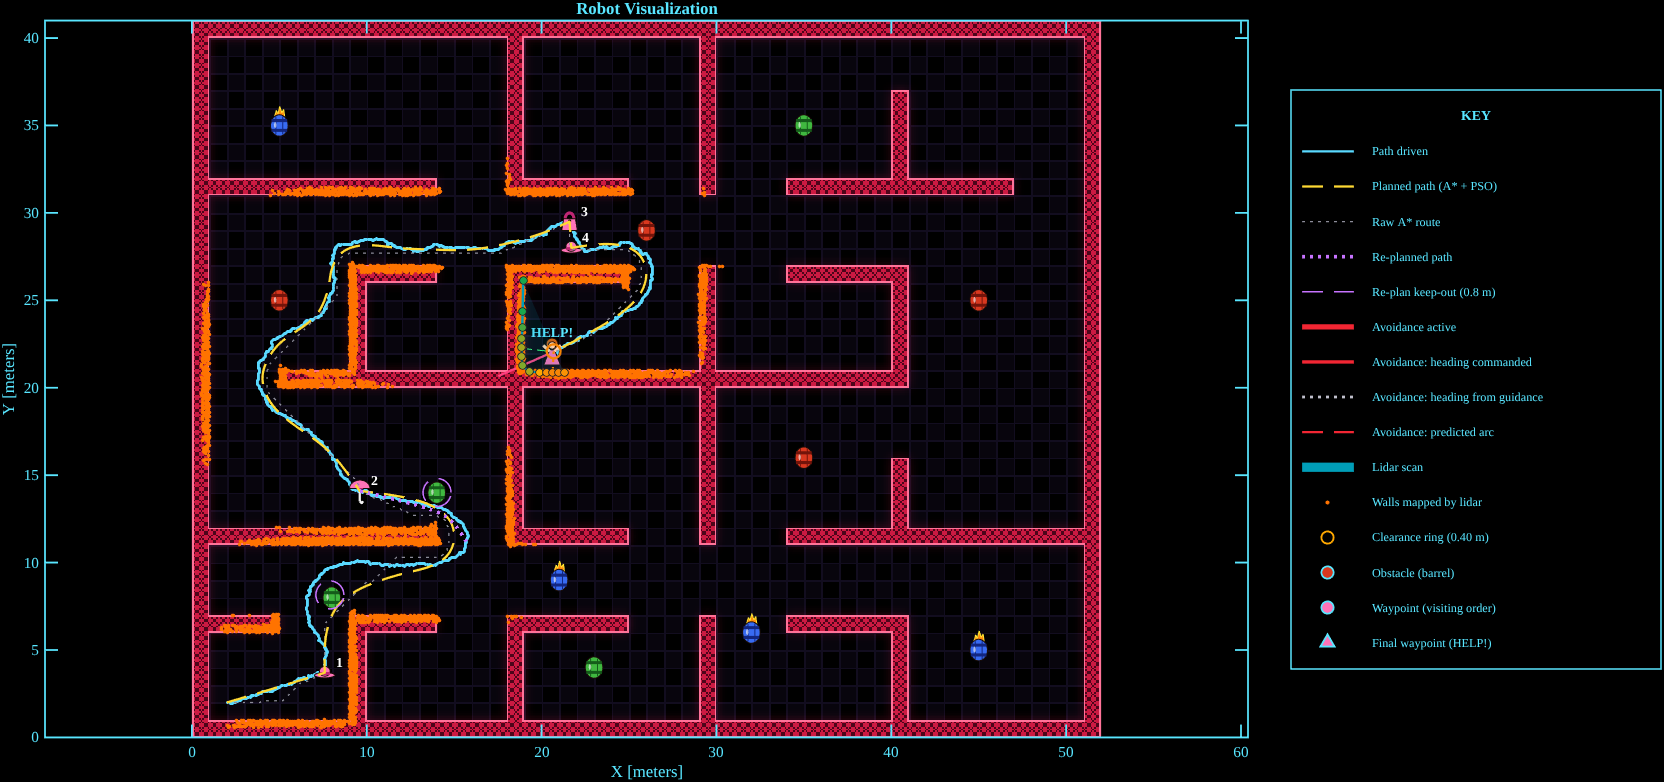

**Figure 1.** A finished mission in the default 'kong' style, with the key on the right. The robot started at the bottom left, visited waypoints 1 to 4 and stopped on the final waypoint in the middle. The yellow planned path lies under the light blue driven path almost everywhere; the two separate between waypoints 1 and 2, where the path was re-planned around two green barrels (violet).

## How the system works

Before the run, `mdl_robot` plans the mission: waypoints, visiting order, an A* route and a smoothed path along it. During the run the signal flow is:

- **Vehicle** outputs a noisy pose and speed.

- **State Estimation and Filtering** turns them into the estimate `x_hat`.

- **Guidance** follows the current path and outputs a heading command `theta_cmd`.

- **Replanner** remembers the obstacles the Object Detector sees and, when one is close to the path still to be driven, re-plans the path around it and hands Guidance the new one.

- **Obstacle avoidance** uses the Lidar Sensor and Object Detector to adjust the heading into `theta_cmd_safe` and a speed factor `v_scale`. It is the close-range backup to the Replanner.

- **Controller** converts these into `v_cmd` and `omega_cmd` for the vehicle.

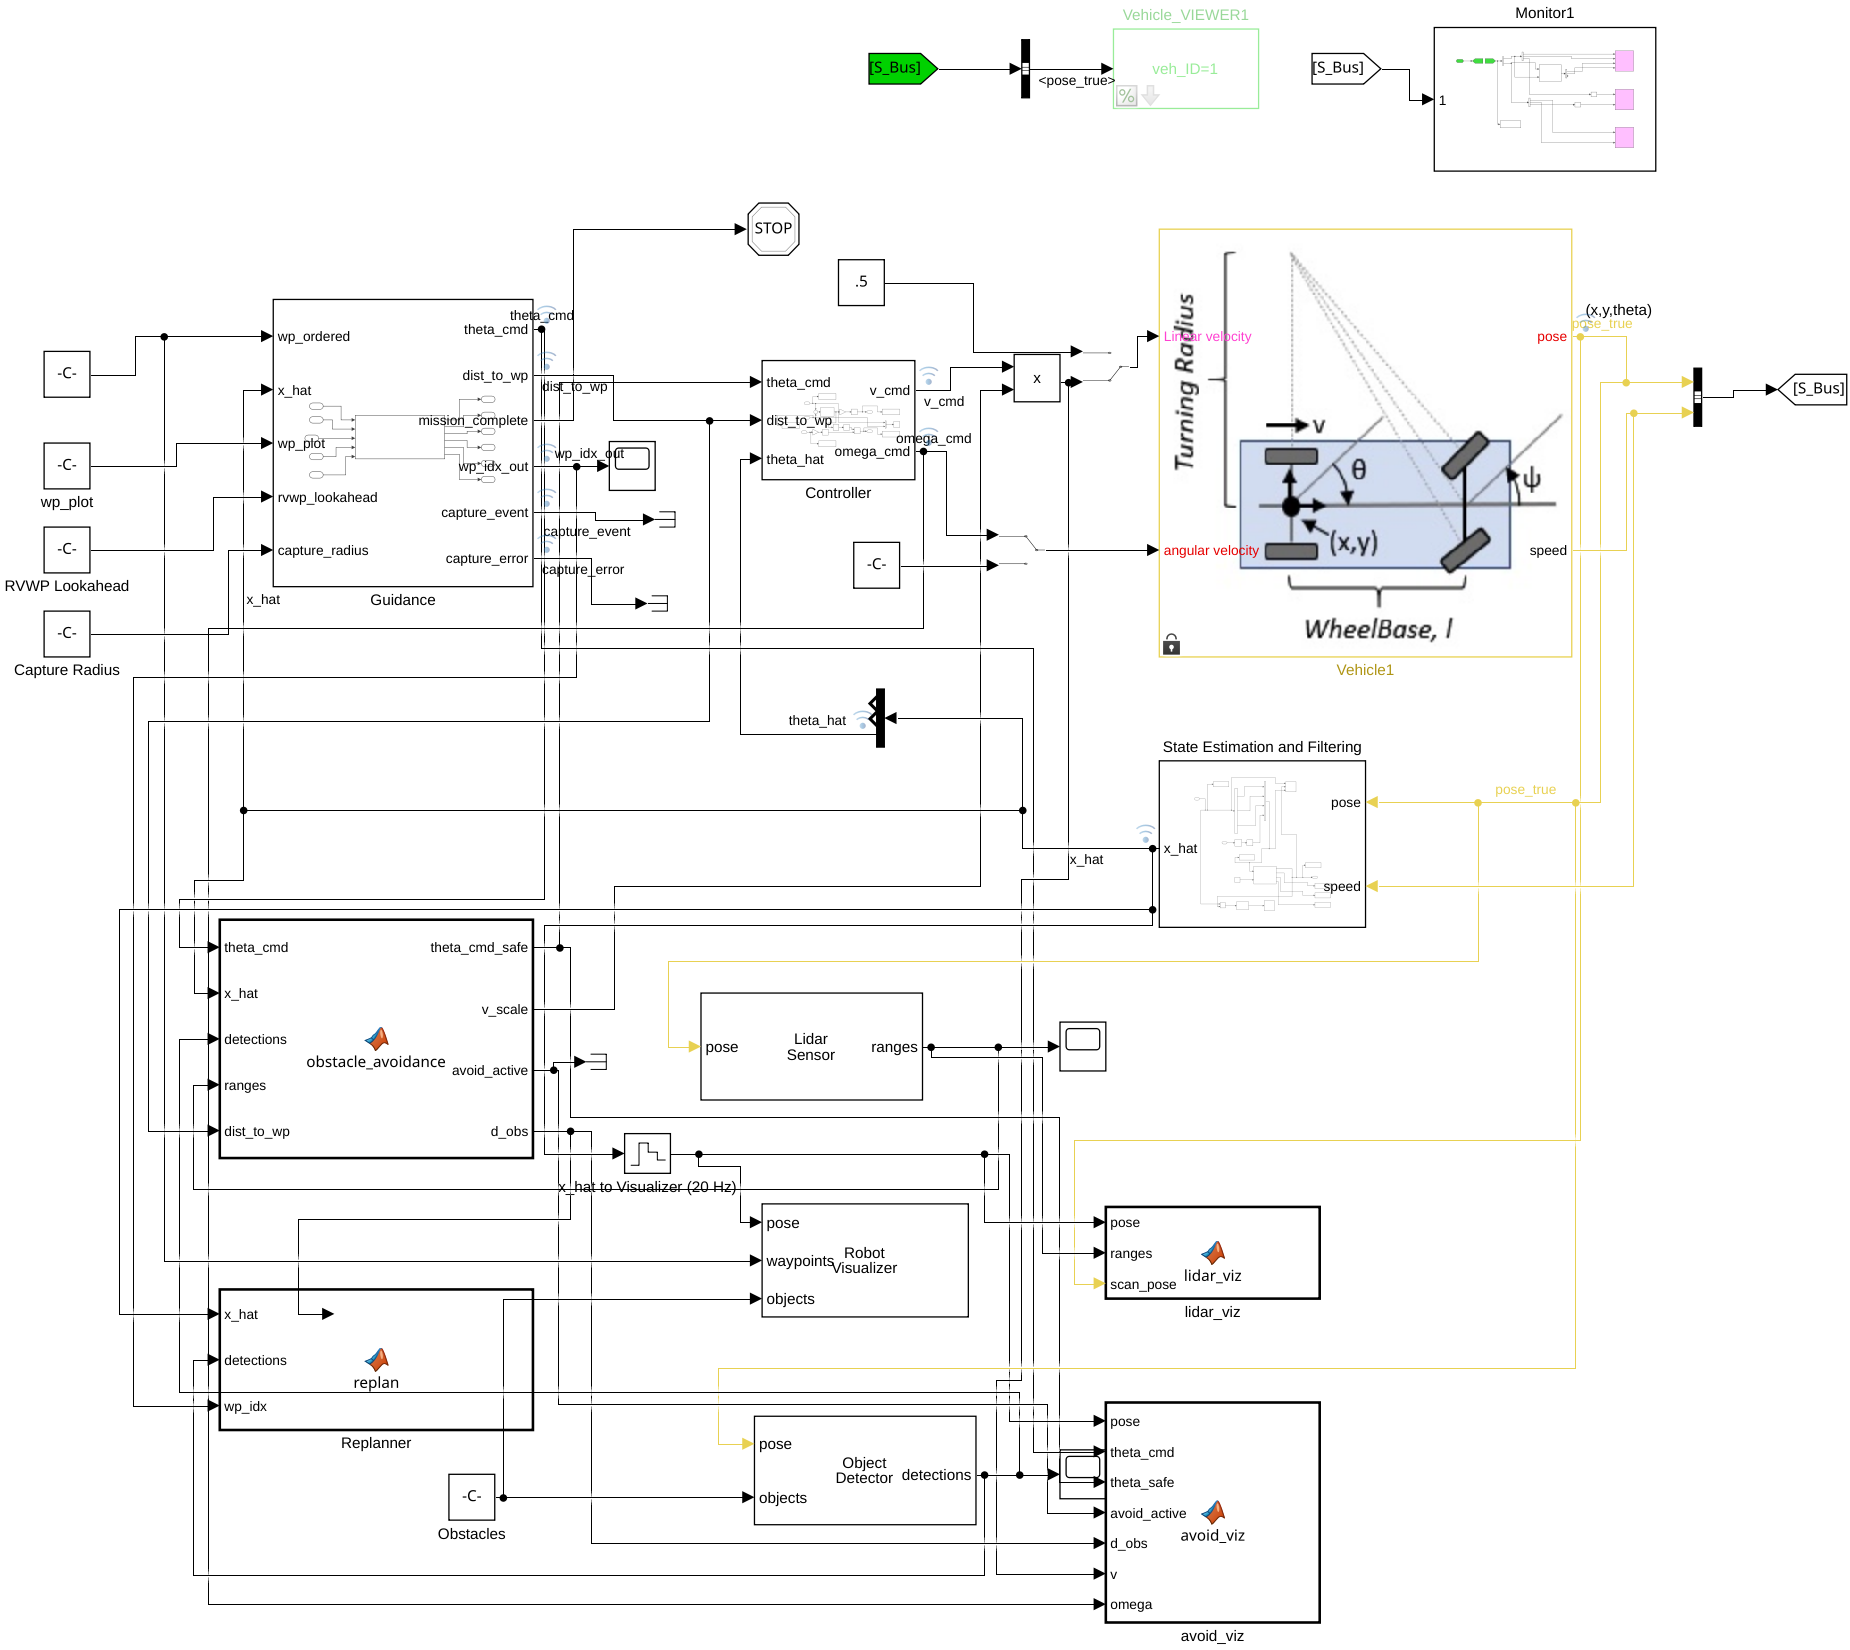

**Figure 2.** The Simulink model. Guidance (top left) sends its heading to the obstacle avoidance block (middle left), which sends the adjusted heading and speed factor to the Controller and the vehicle (top right). The Replanner (bottom left) takes `x_hat`, the detections and the waypoint index, and returns nothing on a signal line: it passes the new path to Guidance through `path_store.m`. `lidar_viz` and `avoid_viz` (bottom right) only draw.

## Mission planning

File: `toolboxes/ground_robot/mdl_robot.m`. The start pose is fixed at x = 2 m, y = 2 m, heading 0 rad.

- **Clearance map.** The walls in `logical_map` are grown by 6 cells with `inflate_map`. The planner works on the corners of the map cells, so the wall cells are first expanded to every corner they touch; this makes the inflation a true distance from the wall faces. The required clearance is 0.40 m (0.25 m robot radius plus 0.15 m); the extra cells leave room for tracking error and estimator noise.

- **Clearance field.** `clearance_field` gives the distance from every grid point to the nearest wall, up to 1.5 m. The smoothing step uses it to measure how close a curve comes to the walls.

- **Waypoints.** `wp_gen` draws 5 random waypoints that are in free space on the clearance map and at least 1.0 m from every obstacle.

- **Distances.** `waypoint_distances` runs A* between every pair of points (start and waypoints) to get real driving distances around the walls, not straight-line distances.

- **Visiting order.** `wp_antColony` orders the waypoints by ant colony optimisation on those distances. Its parameters come from `aco_defaults.m`.

- **Route.** `wp_path` joins the ordered waypoints with A* legs (`A_star.m`, 8-connected, on the clearance map). This decides which way round the walls each leg goes.

- **Smoothing.** `wp_swarm` turns each A* leg into a cubic B-spline by particle swarm optimisation. The control points start on the A* leg, one per metre, and the swarm (30 particles, 150 iterations) shifts each one up to 1.0 m sideways. The cost is the path length plus penalties for curvature, for turns tighter than a 1.0 m radius, for coming within 0.9 m of a wall and, much more heavily, for coming within 0.6 m. A leg whose best curve still comes within 0.6 m of a wall is replaced by its A* leg. The parameters come from `pso_defaults.m`.

- **Replanner set-up.** `obstacle_replan('init', ...)` stores the smoothed legs and the clearance field for re-planning during the run.

The obstacle positions are used only to keep waypoints off the obstacles. The path itself is planned on walls alone; obstacles are handled while driving, from sensor data.

Results left in the base workspace: `wp_list` (unordered waypoints), `wp_ordered` (visiting order), `astar_path` and `astar_dist` (the raw A* path and its length), `path` and `wp_plot` (the smoothed path), `path_dist` (its length), `pso_info` (smoothing results for each leg), `dist_cum` and `history` (ant colony convergence).

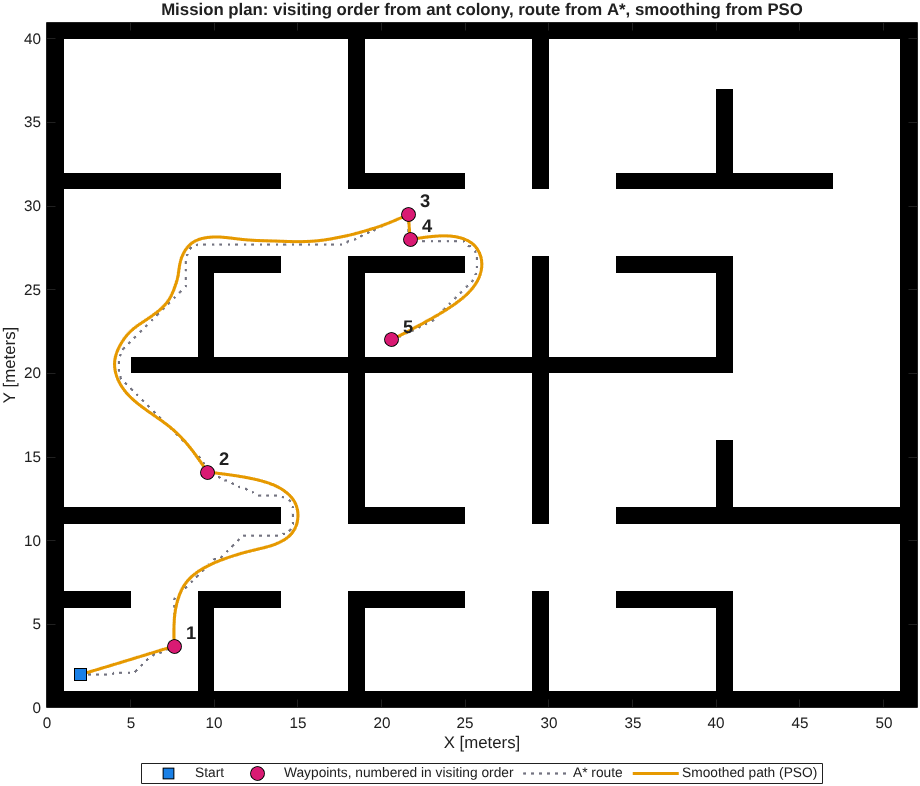

**Figure 3.** The plan for the mission in Figure 1, before it was driven. The waypoints are numbered in the order the ant colony chose. The grey dotted line is the A* route. The solid line is the path after particle swarm smoothing, which is drawn yellow and dashed in the simulation.

## State estimation

Block: "State Estimation and Filtering". A linear Kalman filter running at 100 Hz. The state is `[px, py, theta, v, omega, vx, vy]` with a constant-velocity model, and the measurements are the environment's noisy pose and speed. The pose arrives more slowly than the filter runs, so a pose sample is only used on the step where it changes; in between, only the speed measurement is used. The output `x_hat = [x, y, theta]` feeds guidance, avoidance and the visualizer.

## Guidance

Block: "Guidance". Follows the planned path point by point and captures the waypoints in order. `guidance_block.txt` is a reference copy of the code inside the block.

- A path point counts as reached within 1.0 m; the robot then steers at the next one. Progress along the path can never run past the waypoint currently being chased.

- A waypoint is captured within `capture_radius` (0.8 m).

- The last waypoint uses a 0.10 m capture radius so the mission ends on it. The block then stops the simulation.

- When the Replanner publishes a new path, Guidance switches to it on the next step. If the leg it is driving was re-planned, it restarts from the beginning of the new leg, which is the robot's own position.

Outputs: `theta_cmd`, `dist_to_wp`, `mission_complete`, the current waypoint index, and the capture event and capture error for each waypoint.

## Online re-planning

Block: "Replanner", which calls `toolboxes/ground_robot/obstacle_replan.m` at 100 Hz. It moves the path around an obstacle before the robot reaches it. Obstacle positions come only from the Object Detector; the obstacle file is not read.

- **Remember.** Each detection is converted to world coordinates. A detection within 0.75 m of a known obstacle updates that obstacle's position; any other starts a new one.

- **Confirm.** An obstacle is trusted once it has been detected on 20 steps of the block (0.2 s).

- **Trigger.** A leg still to be driven is re-planned if it passes within 1.0 m of a confirmed obstacle. Re-planning happens at most once per second, and only when an obstacle is new or its position estimate has moved more than 0.3 m.

- **Re-plan.** The obstacle is added to the clearance field, A* finds a new route and `wp_swarm` smooths it. A* first keeps 1.0 m from the obstacle's centre, and falls back to 0.8 m if that leaves no route. The leg the robot is on is re-planned from the robot's position.

- **Hand over.** The new path is published through `path_store.m`, where Guidance picks it up.

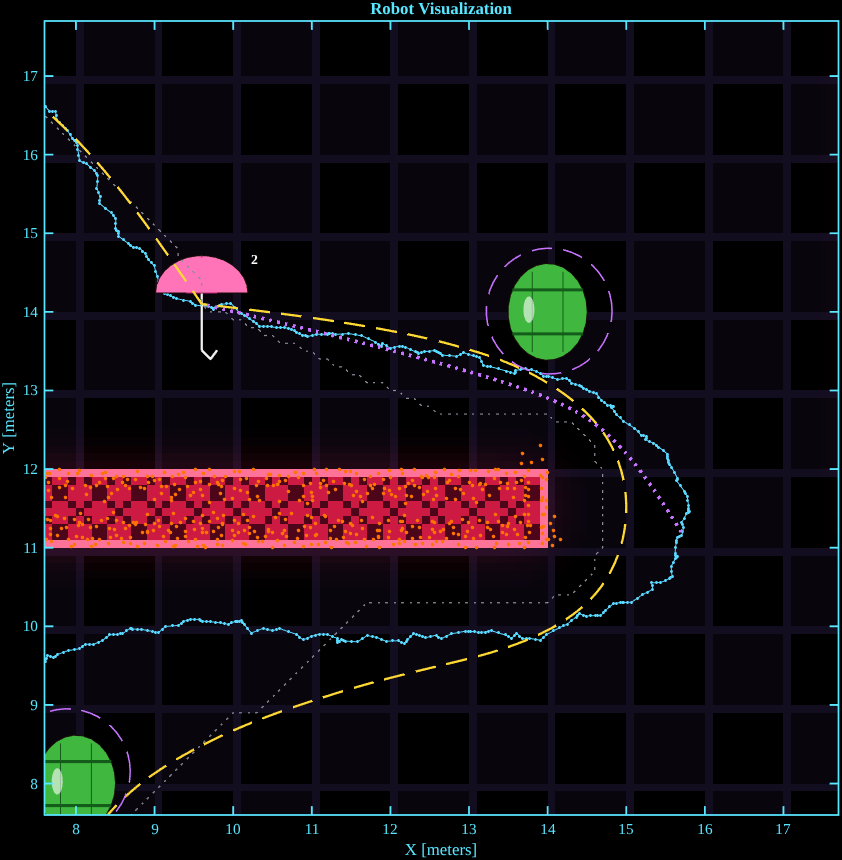

**Figure 4.** Close-up of Figure 1 between waypoints 1 and 2. The yellow planned path passed close to two green barrels, so this leg was re-planned once for each. The violet dashed rings are the 0.8 m keep-outs and the violet dotted line is the newest re-planned path, drawn from where the robot was at the time. The light blue line shows the robot leaving the yellow plan to stay outside both rings.

## Obstacle avoidance

Block: "MATLAB Function" at the top level of the model. A reactive potential-field layer between Guidance and the Controller. Since the Replanner was added it is the close-range backup: it reacts to an obstacle only within 0.8 m. `obstacle_avoidance_block.m` is a reference copy of the code inside the block.

- **Obstacles.** Detections from the Object Detector (range, bearing, label) are converted to world coordinates and remembered. Each remembered obstacle within reach pushes the commanded heading away and adds a sideways slide, so the robot goes around it on the side the waypoint is on.

- **Walls.** Any lidar beam shorter than 1.2 m pushes the heading away from that direction. This backs up the planner's wall clearance.

- **Near a waypoint.** The obstacle reach shrinks with the distance to the waypoint (never below 0.7 m) and the slide fades, so an obstacle beside a waypoint cannot keep the robot from reaching it.

- **Speed.** `v_scale` slows the robot in sharp turns and when an obstacle is within reach, but never below 30 % because a steered vehicle has to keep moving to turn. With the 0.8 m reach the obstacle slow-down comes in over the last 0.1 m, so it acts as a step down in speed, not a gradual one.

- **Smoothing.** The output heading is low-pass filtered so estimator noise is not passed on as steering jitter.

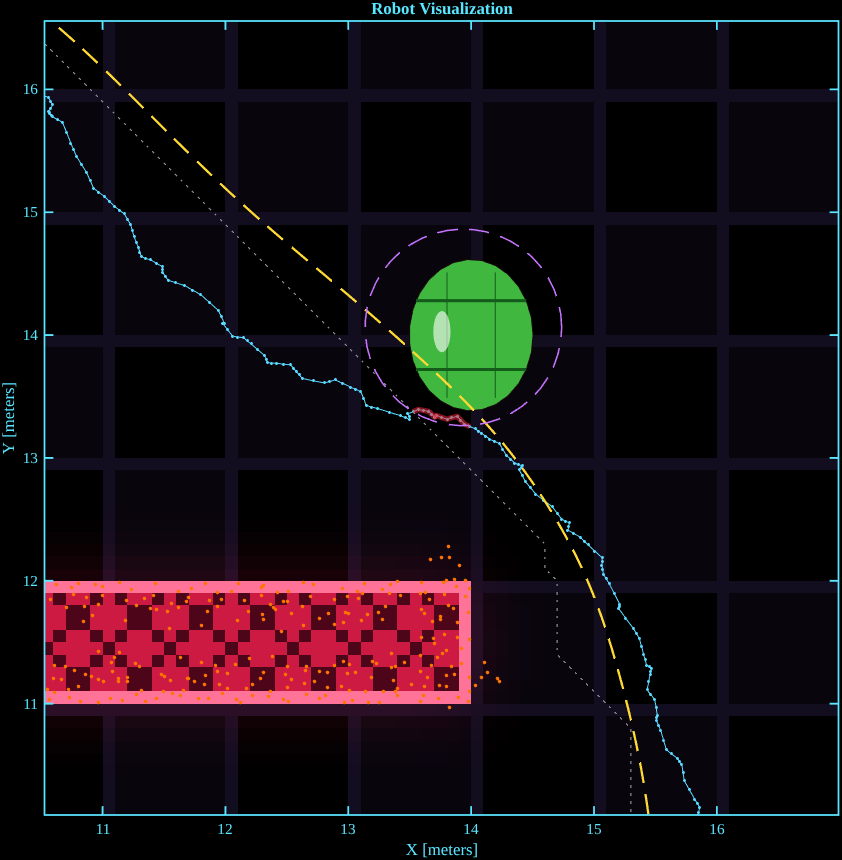

**Figure 5.** Reactive avoidance on a different mission. The driven path (light blue) reaches the edge of an obstacle's keep-out ring, which brings the obstacle within the block's 0.8 m reach. The short red band marks where the block was steering the robot away.

## Controller

Block: "Controller".

- Turn rate: proportional to the wrapped heading error (`K_theta`), limited to `omega_max`.

- Speed: proportional to the distance to the waypoint (`K_dist`), limited to `v_max`, reduced for large heading errors (never below `heading_speed_min`) and multiplied by the avoidance block's `v_scale`.

## Sensors

- **Lidar Sensor**: 13 beams from -90 to +90 degrees, 5 m range.

- **Object Detector**: 120 degree field of view, 5 m range, up to 3 detections, 10 Hz.

If the lidar's beam angles are changed in the Lidar Sensor block, the same `linspace(-pi/2, pi/2, 13)` must be changed in the avoidance block and in the `lidar_viz` block.

## Changing the behaviour

In `toolboxes/ground_robot/mdl_robot.m`:

- Number of waypoints: `no_wps`

- Start pose: `robot.X`, `robot.Y`, `robot.Theta`

- Wall clearance of the planned path: second argument of `inflate_map` (cells of 0.1 m). Keep `c_hard` in `pso_defaults.m` equal to it.

- Waypoint-to-obstacle spacing: last argument of `wp_gen` (m)

In `controller_params.m`:

- Speed and turn-rate limits and gains: `v_max`, `omega_max`, `K_theta`, `K_dist`, `heading_speed_min`

- Waypoint capture radius: `capture_radius`

In `toolboxes/ground_robot/aco_defaults.m`:

- Ant colony parameter set: `ACTIVE` (`'N10'`, `'N20'` or `'original'`)

In `toolboxes/ground_robot/pso_defaults.m`:

- Path smoothing: `particles`, `iterations`, `spacing`, `band`, the clearances `c_hard` and `c_soft`, the tightest turn `kappa_max` and the cost weights

At the top of `toolboxes/ground_robot/obstacle_replan.m`:

- Re-planning: `CONFIRM`, `COOLDOWN`, `MERGE`, `MOVE`, `TRIGGER`, `OBS_CLR`, `OBS_WIDE`

In the top-level "MATLAB Function" block of the model:

- Obstacle and wall avoidance tuning: `d_inf`, `k_rep`, `k_tan`, `D_NEAR`, `d_wall`, `k_wall`, `a_f`

Avoidance tuning has to be changed inside the Simulink block. Editing `obstacle_avoidance_block.m` alone does nothing; it is only the reference copy, so keep the two the same. The Guidance block and `guidance_block.txt` work the same way.

In `draw_lidar_view.m`:

- Arena look: `ARENA_STYLE`

## Data logged by a run

These variables are in the base workspace after a run and can be used for the report's plots and metrics.

- `xhat_log`: estimated pose from the Kalman filter

- `pose_log`, `z_log`: measured (noisy) pose and the filter's measurement input

- `innov_log`, `K_log`, `P_log`: filter innovation, Kalman gain and error covariance

- `d_obs_log`: distance to the nearest remembered obstacle ahead (`inf` when none)

- `groud_robot_state`: vehicle state logged by the Monitor block

- `tout`: simulation time

## File guide

In `sim_env`:

- `startupGround.m`: run this first; sets the path and opens the model

- `controller_params.m`: controller and guidance parameters

- `draw_lidar_view.m`: lidar overlay, planned paths and arena styling for the visualizer

- `draw_avoid_view.m`: avoidance overlay for the visualizer

- `draw_sensor_waves.m`: alternative animated lidar overlay (not wired into the model)

- `obstacle_avoidance_block.m`: reference copy of the avoidance block's code

- `guidance_block.txt`: reference copy of the Guidance block's code

- `guidance_block_old.txt`, `avoidance_block_old.txt`: the two blocks' code from before the Replanner was added, kept for comparison

- `add_replanner.m`, `add_avoid_viz.m`: one-off scripts that added the Replanner and avoid_viz blocks to the model. Both have been applied and saved, so they do not need to be run again.

- `complexMap_air_ground.mat`, `obstacles_air_ground.mat`: the map and the obstacles

- `toolboxes/MRTB`: Mobile Robotics Simulation Toolbox (supplied)

In `sim_env/toolboxes/ground_robot`:

- `sl_groundvehicleDynamics.slx`: the Simulink model

- `mdl_robot.m`: mission set-up and planning, run at model start

- `wp_gen.m`: random waypoint generation

- `waypoint_distances.m`: A* distance between every pair of points

- `wp_antColony.m`: ant colony optimisation of the visiting order

- `aco_defaults.m`: ant colony parameter sets

- `A_star.m`: A* grid search

- `inflate_map.m`: grows walls by a clearance radius

- `wp_path.m`: A* route for each leg between the ordered waypoints

- `clearance_field.m`: distance from every grid point to the nearest wall

- `wp_swarm.m`: particle swarm smoothing of each leg

- `pso_defaults.m`: particle swarm parameters

- `obstacle_replan.m`: online re-planning around detected obstacles

- `path_store.m`: holds the current path so the Replanner can pass a new one to Guidance

- `path_prune.m`, `path_simplify.m`, `map_scale.m`: path and map helpers, not used by the current pipeline

## Troubleshooting

- **"Undefined function or variable" when pressing Run.** `startupGround` was not run, or MATLAB's current folder is not `sim_env`.

- **The window is plain white.** `draw_lidar_view.m` must be in `sim_env`. If the lidar overlay is there but the map is still white, `ARENA_STYLE` is set to `'off'`.

- **"wp_path:noRoute" error at start.** No path exists between two waypoints on the clearance map. Run again to generate a new mission.

- **The simulation runs slowly.** The overlays redraw at up to 10 frames per second. Lower `MAX_FPS` in `draw_lidar_view.m` and `draw_avoid_view.m`. The simulation also pauses briefly at each re-plan while A* and the swarm run.

- **The model will not open, or opens with a version error.** It was saved in R2026a. Open it in R2026a or newer.

## Mobile Robotics Simulation Toolbox

The sensor, visualizer and vehicle blocks come from the Mobile Robotics Simulation Toolbox. Its documentation is in `toolboxes/MRTB/doc` and its examples in `toolboxes/MRTB/examples`.

[1] Mobile Robotics Simulation Toolbox. Copyright 2018-2019 The MathWorks, Inc. [https://github.com/mathworks-robotics/mobile-robotics-simulation-toolbox](https://github.com/mathworks-robotics/mobile-robotics-simulation-toolbox)